## Classification

#### 1. **Understand the feature set in space:**

First of all, we form our training and test feature sets and the corresponding labels set. We want to observe how our feature points for distinct classes are scattered in the feature space, therefore we use the scatterplot to plot the feature sets of 5 unique classes all at once. From the scatterplot we observe that the features of different classes form something resembling the shape of a cloud, being enough separated between each other to not to apply any of the feature space transformation techniques. 

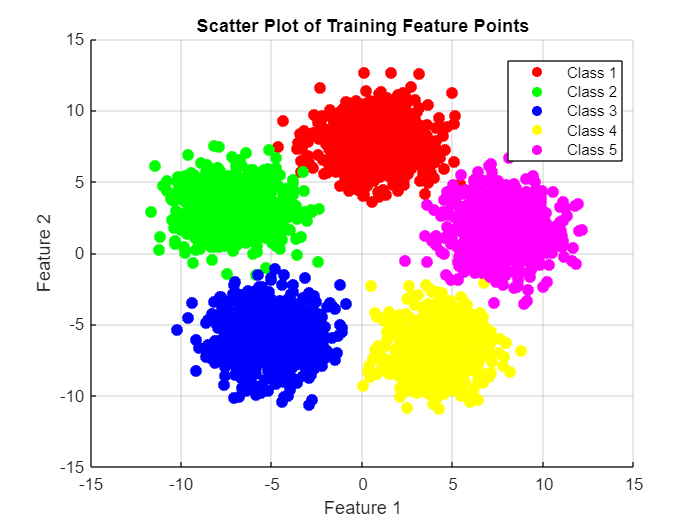

%%%%%%%%%%%%
% I cannot provide my own training and test data
% Use your own dataset and initialize Utrain, Ytrain, Utest, Ytest
%%%%%%%%%%%%

colors = ['r', 'g', 'b', 'y', 'm'];

figure;
hold on; 
grid on;

% Plotting the scatterplot of the feature space
for i = 1:size(unique(Ytrain))
    scatter(Utrain(Ytrain==i,1), Utrain(Ytrain==i,2), 50, colors(i), 'filled');
end

title('Scatter Plot of Training Feature Points');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1', 'Class 2', 'Class 3', 'Class 4','Class 5','Location', 'best');
grid on;
hold off;

#### 2. **Define the required classification algorithm:**

For this specific problem, the features of different classes can be well separated by the linear decision boundaries. One of the good and robust models that I have chosen for solving the following task is the **Linear DIscriminant Analysis (LDA)** with the common covariance matrix. The LDA model uses the Bayes' Theorem to estimate the posterior probability of selecting the class $C_{i\;}$given the new input $u\left(t\right)$. In the **"myLDA.m"** function, by estimating the prior probabilities of the classes, the means of the features corresponding to the specific classes, and the shared covariance matrix, we found the coefficients of the linear decision boundaries between the classes in the feature space. The linear decision boundary $z_i \left(t\right)$ in the multiclass problem is computed as follows:

$z_i \left(t\right)=u^T \left(t\right)\beta +\beta_0$,

where

$\beta =\Sigma^{-1} \mu_i$ and $\beta_0 =-\frac{1}{2}\mu_i^T \Sigma^{-1} \mu_i +\textrm{logP}\left(C_i \right)$,

where $\mu_i$ is the mean of the class i $\left(C_i \right)$, $\Sigma$ is the shared covariance matrix, $P\left(C_i \right)$ is the prior probability of the class i, and $\beta$, $\beta_0$ are the coefficients of the linear decision boundary.

Having found the coefficients of the discriminant functions, in the **"classify_LDA.m"** function, we classify our test input by substituting our feature data into the discriminant function and calculating the posterior probabilities of selecting the class $C_{i\;}$. The posteriors are calculated as follows:

$P\left(C_i |\textrm{Utest}\right)=\frac{e^{z_i \left(t\right)} }{\sum_{k=1}^M e^{z_k \left(t\right)} }$,

where M = 5, which equals to the number of distinct classes in the set. 

After computing the posteriors for each test input sample, we look at the maximum value across all the classes and assign that class to the sample, which corresponds to the highest posterior value. 

% Calculating the beta0 and beta parameters for the linear decision
% boundaries between 5 distinct classes
[beta0, beta] = myLDA(Utrain, Ytrain);

disp("Constant coefficients:")

Constant coefficients:


disp(beta0)

  -14.0667
  -13.7306
  -13.9310
  -14.1632
  -14.0914



disp("Linear coefficients:")

Linear coefficients:


disp(beta)

    0.3116   -2.8663   -2.1131    1.6706    3.1042
    3.1718    1.2564   -2.3607   -2.7164    0.6865



% Finding the predictions of training and test sets using the custom
% "classify_LDA" function
[train_predictions, train_posterior] = classify_LDA(Utrain, beta0, beta);
[test_predictions, test_posterior] = classify_LDA(Utest, beta0, beta);

#### 3. **Verify and test your classificator:**

We have classified the Utest dataset, and now we need to verify our classification by computing the training and test accuracies and errors. The training error is expectedly less than the test error as the LDA classifier has already seen the training data, and both errors are less than 1%, which is an excellent performance of the classification using LDA. Additionally, we plot the confusion matrix to observe what classes have been misclassified the most. 

% Computing the training and test accuracies and corresponding errors
train_accuracy = sum(train_predictions == Ytrain) / length(Ytrain);
test_accuracy = sum(test_predictions == Ytest) / length(Ytest);
train_error = 1 - train_accuracy;
test_error = 1 - test_accuracy;
fprintf('Training error = %.4f %%\n', 100*train_error);

Training error = 0.2286 %


fprintf('Test error = %.4f %%\n', 100*test_error);

Test error = 0.2667 %


% Computing the confusion matrix on the test set
confusion_mat = confusionmat(Ytest, test_predictions);
fprintf('Confusion matrix:\n');

Confusion matrix:


disp(confusion_mat)

   301     0     0     0     0
     0   290     0     0     0
     0     1   303     1     0
     0     0     0   302     0
     2     0     0     0   300



In the **"visualize_LDA.m"** function, we plot the test feature points along with the discriminant functions that are drawn between the "adjacent" (relative) classes. The input space is thus divided into the 5 regions separated by 5 linear decision boundaries (hyperplanes), where the hyperplane separating classes k and j is descibed by the equation below:

$z_k \left(t\right)-z_j \left(t\right)=0$ that is $u^T \left(t\right)\beta_k +\beta_{0,k} =u^T \left(t\right)\beta_j +\beta_{0,j}$.

The lines are drawn entirely, without stopping at the center of the space. 

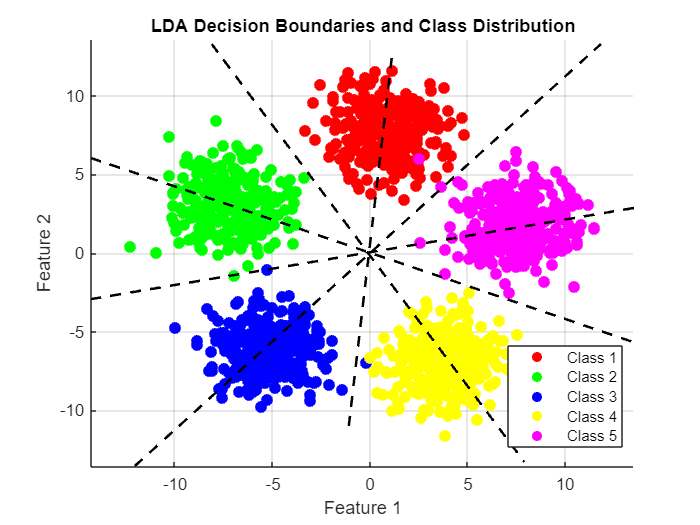

% Visualizing all the decision boundaries (linear discriminant functions)
% between the relative classes
visualize_LDA(Utest, Ytest, beta0, beta)

In this section, we train and test the linear LDA classifier, which is constructed using the built-in MATLAB function classed **"fitcdiscr"**. We want to compare the performances and the coefficients given by the custom and MATLAB's classifiers. As you see, the test error is identical to the one we obtained by computing the posteriors manually. 

% Train LDA classifier using built-in function
lda_model = fitcdiscr(Utrain, Ytrain, 'DiscrimType', 'linear');

% Predict on test data
Ypred = predict(lda_model, Utest);

% Calculate error rate
test_error = 1 - sum(Ypred == Ytest) / length(Ytest);
fprintf('Test error rate: %.4f%%\n', 100*test_error);

Test error rate: 0.2667%


In terms of the coefficients, the normalized constant coefficients ($\beta_0$) are identical to those obtained by the "myLDA.m" function; however, the linear coefficients $\beta$ tend to be different from ours. In fact, this does not pose any issue because the LDA can have multiple equivalent solutions that produce the same decision boundaries. The coefficients can differ while still giving identical classifications because what matters is the relative orientation of the decision boundaries.

% Initialize matrices to store all coefficients
beta_matlab = zeros(2, 5);    % 2 features x 5 classes
beta0_matlab = zeros(5, 1);   % 5 classes

% Extract coefficients for each class
for i = 2:5
    beta_matlab(:,i) = lda_model.Coeffs(i).Linear;
    beta0_matlab(i) = lda_model.Coeffs(i).Const;
end

% Normalize both sets of beta0
beta0_normalized = beta0 - mean(beta0);
beta0_matlab_normalized = beta0_matlab - mean(beta0_matlab);

disp("Normalized constant coefficients from myLDA and fitcdiscr:")

Normalized constant coefficients from myLDA and fitcdiscr:


disp([beta0_matlab_normalized beta0_matlab_normalized])

   -0.0701   -0.0701
    0.2660    0.2660
    0.0656    0.0656
   -0.1666   -0.1666
   -0.0948   -0.0948



disp("Linear coefficients from myLDA:")

Linear coefficients from myLDA:


disp(beta)

    0.3116   -2.8663   -2.1131    1.6706    3.1042
    3.1718    1.2564   -2.3607   -2.7164    0.6865



disp("Linear coefficients from fitcdiscr:")

Linear coefficients from fitcdiscr:


disp(beta_matlab)

         0   -3.1779   -2.4247    1.3590    2.7926
         0   -1.9155   -5.5325   -5.8882   -2.4853



As we plot here the decision boundaries computed by the MATLAB's LDA classifier, we prove that the boundaries seems to be identical to those we have visualized above using our "visualized_LDA.m" function. 

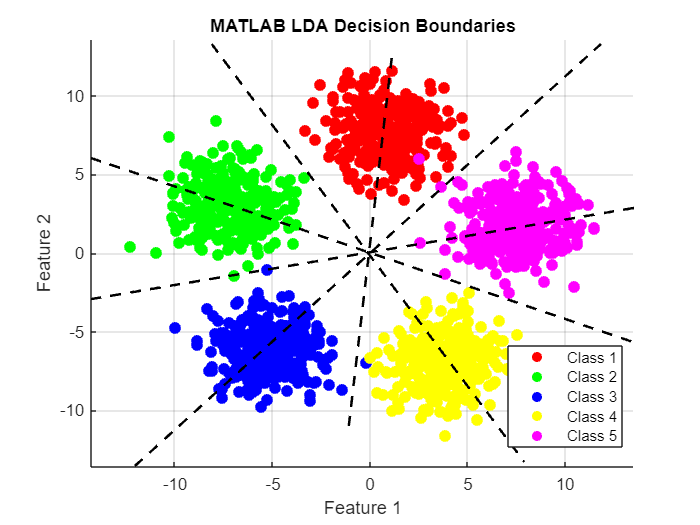

visualize_LDA(Utest, Ytest, beta0_matlab, beta_matlab)
title('MATLAB LDA Decision Boundaries');